clc
clear
a = 1.162254;
b_0 = 1.034930;
b_1 = 0.274702;

### Main Planet transformation.


$$T_f = \frac{a}{s^{3} + b_0s^2 + b_1s}$$
 

% Define the transfer function G
s = tf('s');
G = (1.162254) / (s^3 + 1.034930*s^2 + 0.274702*s)

G =
 
            1.162
  --------------------------
  s^3 + 1.035 s^2 + 0.2747 s
 
Continuous-time transfer function.



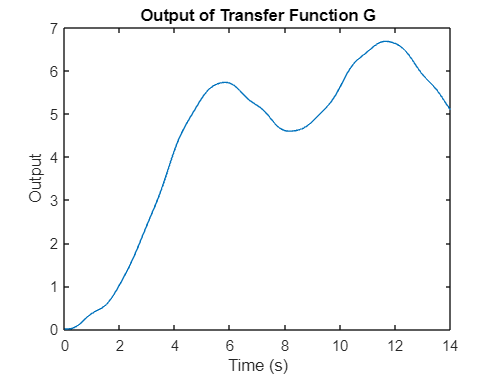


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('Output of Transfer Function G');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  1.445e-07 z^3 + 4.336e-07 z^2 + 4.336e-07 z + 1.445e-07
  -------------------------------------------------------
             z^3 - 2.99 z^2 + 2.979 z - 0.9897
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  1.445e-07 + 4.336e-07 z^-1 + 4.336e-07 z^-2 + 1.445e-07 z^-3
  ------------------------------------------------------------
            1 - 2.99 z^-1 + 2.979 z^-2 - 0.9897 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num = 1.0e-06 *

    0.1445    0.4336    0.4336    0.1445


Den = -Gz.Denominator{1}

Den =    -1.0000    2.9897   -2.9794    0.9897


Num = Gz.Numerator{1}

Num = 1.0e-06 *

    0.1445    0.4336    0.4336    0.1445


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9897   -2.9794    0.9897


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 1.445328504985901e-07
Num(2) = 4.335985514957702e-07
Num(3) = 4.335985514957702e-07
Num(4) = 1.445328504985901e-07



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.989676720056202
Den(3) = -2.979380768708803
Den(4) = 0.9897040486526006


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0012    0.0015    0.0019    0.0024    0.0030    0.0036    0.0043    0.0051    0.0060    0.0070    0.0081    0.0093    0.0106    0.0120    0.0135    0.0152    0.0170    0.0189    0.0209    0.0231    0.0254    0.0279    0.0305    0.0332    0.0361    0.0391    0.0423    0.0456    0.0491    0.0527    0.0564    0.0603    0.0644    0.0685    0.0728    0.0773    0.0818    0.0865    0.0913


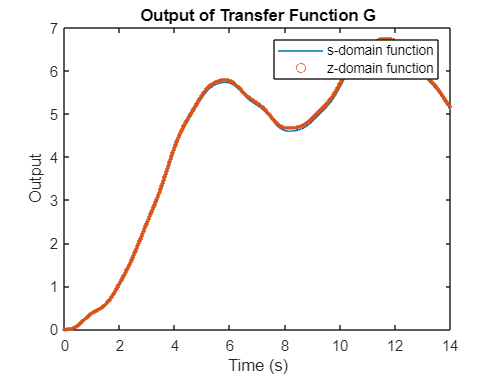

scatter(t, y, 3);
legend('s-domain function', 'z-domain function')

#### Regressor filters.

### 1. first filter.


$$F_1 = \frac{-s^2}{s^{3} + 3s^2 + 3s+1}$$


clc
clear

% Define the transfer function G
s = tf('s');
G = (-s^2) / (s+1)^3

G =
 
          -s^2
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



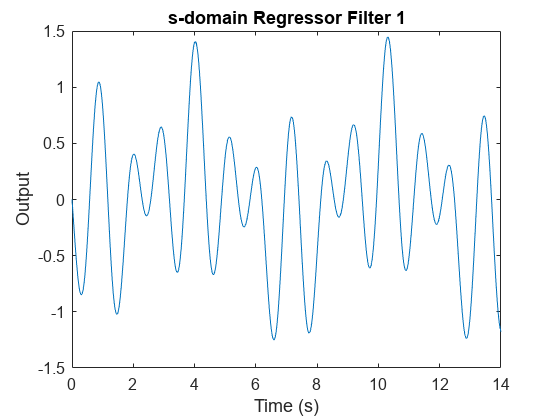


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Regressor Filter 1');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  -0.004926 z^3 + 0.004926 z^2 + 0.004926 z - 0.004926
  ----------------------------------------------------
           z^3 - 2.97 z^2 + 2.941 z - 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  -0.004926 + 0.004926 z^-1 + 0.004926 z^-2 - 0.004926 z^-3
  ---------------------------------------------------------
          1 - 2.97 z^-1 + 2.941 z^-2 - 0.9704 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =    -0.0049    0.0049    0.0049   -0.0049


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9701   -2.9406    0.9704


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = -0.004925743796549048
Num(2) = 0.004925743796549048
Num(3) = 0.004925743796549048
Num(4) = -0.004925743796549048



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.970149253731343
Den(3) = -2.940595529813618
Den(4) = 0.9704452909335155


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y =    -0.0184   -0.0556   -0.0933   -0.1316   -0.1703   -0.2091   -0.2480   -0.2869   -0.3255   -0.3638   -0.4015   -0.4386   -0.4750   -0.5104   -0.5447   -0.5778   -0.6096   -0.6399   -0.6687   -0.6958   -0.7210   -0.7444   -0.7657   -0.7849   -0.8019   -0.8166   -0.8290   -0.8389   -0.8464   -0.8513   -0.8537   -0.8534   -0.8506   -0.8450   -0.8369   -0.8261   -0.8126   -0.7965   -0.7779   -0.7566   -0.7329   -0.7068   -0.6782   -0.6473   -0.6142   -0.5790   -0.5417   -0.5025   -0.4614   -0.4186


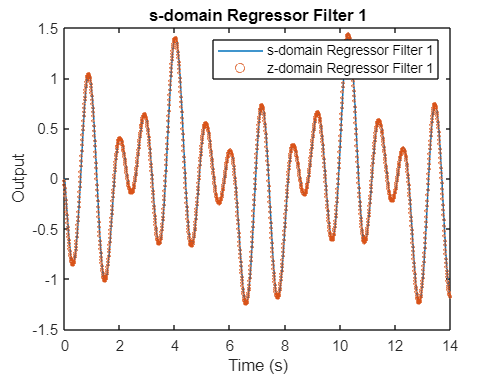

scatter(t, y, 3);
legend('s-domain Regressor Filter 1', 'z-domain Regressor Filter 1')

### 2. Second filter.


$$F_2 = \frac{-s}{s^{3} + 3s^2 + 3s+1}$$


clc
clear

% Define the transfer function G
s = tf('s');
G = (-s) / (0.1*s+0.1)^3

G =
 
                    -s
  ---------------------------------------
  0.001 s^3 + 0.003 s^2 + 0.003 s + 0.001
 
Continuous-time transfer function.



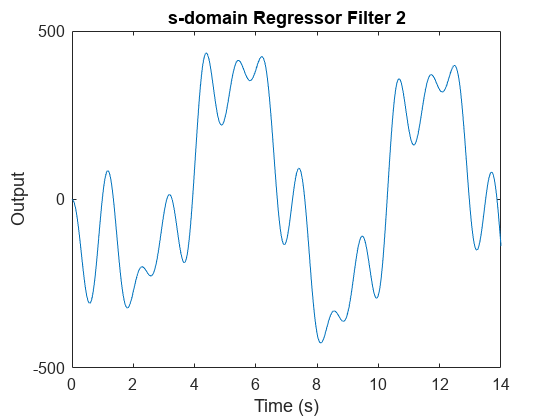


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Regressor Filter 2');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  -0.02463 z^3 - 0.02463 z^2 + 0.02463 z + 0.02463
  ------------------------------------------------
         z^3 - 2.97 z^2 + 2.941 z - 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  -0.02463 - 0.02463 z^-1 + 0.02463 z^-2 + 0.02463 z^-3
  -----------------------------------------------------
        1 - 2.97 z^-1 + 2.941 z^-2 - 0.9704 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =    -0.0246   -0.0246    0.0246    0.0246


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9701   -2.9406    0.9704


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = -0.02462871898274523
Num(2) = -0.02462871898274523
Num(3) = 0.02462871898274523
Num(4) = 0.02462871898274523



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.970149253731343
Den(3) = -2.940595529813618
Den(4) = 0.9704452909335155


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y =    -0.0920   -0.4618   -1.2064   -2.3313   -3.8407   -5.7375   -8.0232  -10.6976  -13.7594  -17.2057  -21.0321  -25.2329  -29.8008  -34.7273  -40.0025  -45.6149  -51.5520  -57.7998  -64.3430  -71.1654  -78.2494  -85.5764  -93.1266 -100.8794 -108.8132 -116.9057 -125.1335 -133.4729 -141.8994 -150.3878 -158.9127 -167.4482 -175.9681 -184.4461 -192.8557 -201.1703 -209.3635 -217.4091 -225.2811 -232.9536 -240.4015 -247.5999 -254.5247 -261.1525 -267.4603 -273.4265 -279.0299 -284.2506 -289.0697 -293.4694


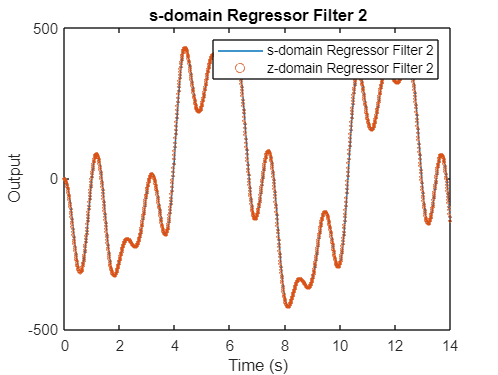

scatter(t, y, 3);
legend('s-domain Regressor Filter 2', 'z-domain Regressor Filter 2')

### 3. Third filter.


$$F_3 = \frac{s}{s^{3} + 3s^2 + 3s+1}$$


clc
clear

% Define the transfer function G
s = tf('s');
G = (s) / (0.1*s+0.1)^3

G =
 
                     s
  ---------------------------------------
  0.001 s^3 + 0.003 s^2 + 0.003 s + 0.001
 
Continuous-time transfer function.



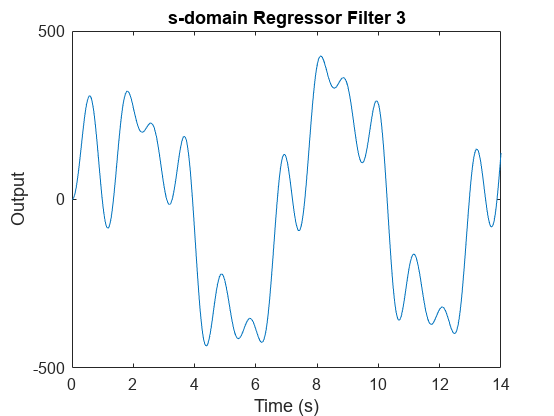


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Regressor Filter 3');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  0.02463 z^3 + 0.02463 z^2 - 0.02463 z - 0.02463
  -----------------------------------------------
         z^3 - 2.97 z^2 + 2.941 z - 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  0.02463 + 0.02463 z^-1 - 0.02463 z^-2 - 0.02463 z^-3
  ----------------------------------------------------
        1 - 2.97 z^-1 + 2.941 z^-2 - 0.9704 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =     0.0246    0.0246   -0.0246   -0.0246


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9701   -2.9406    0.9704


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 0.02462871898274523
Num(2) = 0.02462871898274523
Num(3) = -0.02462871898274523
Num(4) = -0.02462871898274523



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.970149253731343
Den(3) = -2.940595529813618
Den(4) = 0.9704452909335155


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y =     0.0920    0.4618    1.2064    2.3313    3.8407    5.7375    8.0232   10.6976   13.7594   17.2057   21.0321   25.2329   29.8008   34.7273   40.0025   45.6149   51.5520   57.7998   64.3430   71.1654   78.2494   85.5764   93.1266  100.8794  108.8132  116.9057  125.1335  133.4729  141.8994  150.3878  158.9127  167.4482  175.9681  184.4461  192.8557  201.1703  209.3635  217.4091  225.2811  232.9536  240.4015  247.5999  254.5247  261.1525  267.4603  273.4265  279.0299  284.2506  289.0697  293.4694


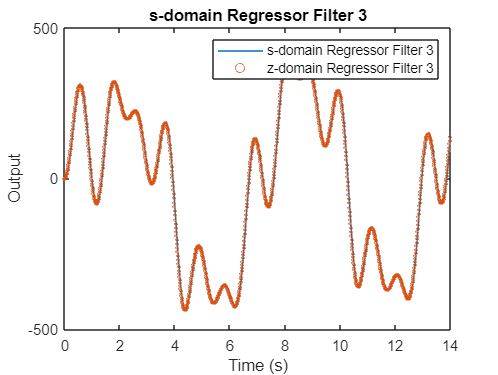

scatter(t, y, 3);
legend('s-domain Regressor Filter 3', 'z-domain Regressor Filter 3')

### 4. Forth filter.


$$F_4 = \frac{1}{s^{3} + 3s^2 + 3s+1}$$


clc
clear

% Define the transfer function G
s = tf('s');
G = (1) / (0.1*s+0.1)^3

G =
 
                     1
  ---------------------------------------
  0.001 s^3 + 0.003 s^2 + 0.003 s + 0.001
 
Continuous-time transfer function.



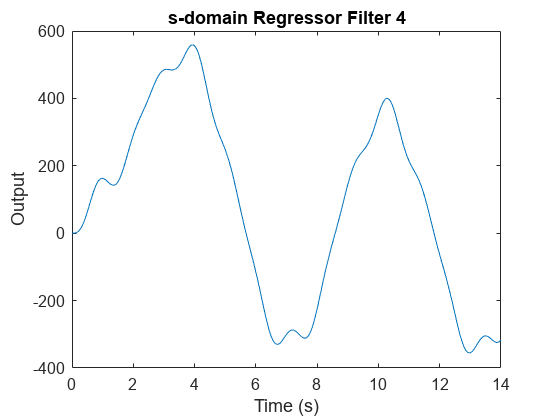


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Regressor Filter 4');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  0.0001231 z^3 + 0.0003694 z^2 + 0.0003694 z + 0.0001231
  -------------------------------------------------------
             z^3 - 2.97 z^2 + 2.941 z - 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  0.0001231 + 0.0003694 z^-1 + 0.0003694 z^-2 + 0.0001231 z^-3
  ------------------------------------------------------------
            1 - 2.97 z^-1 + 2.941 z^-2 - 0.9704 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num = 1.0e-03 *

    0.1231    0.3694    0.3694    0.1231


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9701   -2.9406    0.9704


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 0.0001231435949137262
Num(2) = 0.0003694307847411785
Num(3) = 0.0003694307847411785
Num(4) = 0.0001231435949137262



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.970149253731343
Den(3) = -2.940595529813618
Den(4) = 0.9704452909335155


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y =     0.0005    0.0032    0.0116    0.0293    0.0601    0.1080    0.1768    0.2704    0.3927    0.5475    0.7387    0.9700    1.2452    1.5679    1.9415    2.3696    2.8554    3.4022    4.0129    4.6904    5.4375    6.2566    7.1502    8.1202    9.1686   10.2972   11.5074   12.8005   14.1773   15.6388   17.1853   18.8171   20.5342   22.3362   24.2227   26.1929   28.2455   30.3794   32.5928   34.8840   37.2508   39.6908   42.2014   44.7798   47.4229   50.1273   52.8896   55.7060   58.5726   61.4853


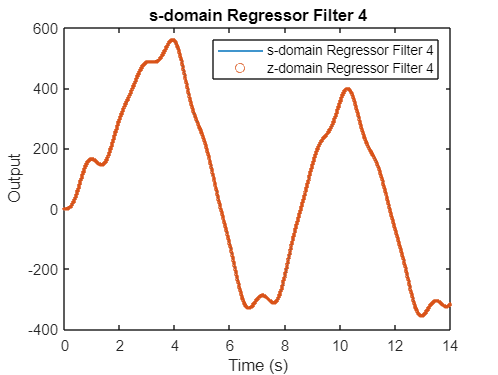

scatter(t, y, 3);
legend('s-domain Regressor Filter 4', 'z-domain Regressor Filter 4')

### 5. Fifth filter.


$$F_5 = \frac{s^3}{s^{3} + 3s^2 + 3s+1}$$


clc
clear

% Define the transfer function G
s = tf('s');
G = (s^3) / (0.1*s+0.1)^3

G =
 
                    s^3
  ---------------------------------------
  0.001 s^3 + 0.003 s^2 + 0.003 s + 0.001
 
Continuous-time transfer function.



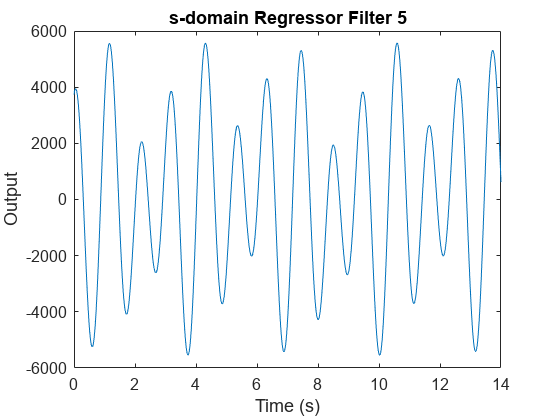


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Regressor Filter 5');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  985.1 z^3 - 2955 z^2 + 2955 z - 985.1
  -------------------------------------
    z^3 - 2.97 z^2 + 2.941 z - 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  985.1 - 2955 z^-1 + 2955 z^-2 - 985.1 z^-3
  ------------------------------------------
   1 - 2.97 z^-1 + 2.941 z^-2 - 0.9704 z^-3
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num = 1.0e+03 *

    0.9851   -2.9554    2.9554   -0.9851


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    2.9701   -2.9406    0.9704


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 985.1487593098094
Num(2) = -2955.446277929428
Num(3) = 2955.446277929428
Num(4) = -985.1487593098094



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 2.970149253731343
Den(3) = -2.940595529813618
Den(4) = 0.9704452909335155


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 + Num(3) * uk_2 + Num(4)*uk_3;
        yterms = Den(2)* yk_1 + Den(3) * yk_2 + Den(4)*yk_3;
        y(i) = uterms + yterms;      
    elseif i == 2
        uterms = Num(1)*u(i) + Num(2)*u(i-1) + Num(3) * uk_1 + Num(4)*uk_2;
        yterms = Den(2)* y(i-1) + Den(3) * yk_1 + Den(4)*yk_2;
        y(i) = uterms + yterms;
    elseif i == 3
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*uk_1;
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*yk_1;
        y(i) = uterms + yterms;   
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1)+ Num(3) * u(i-2) + Num(4)*u(i-3);
        yterms = Den(2)* y(i-1) + Den(3) * y(i-2) + Den(4)*y(i-3);
        y(i) = uterms + yterms; 
    end
end

y

y = 1.0e+03 *

    3.6808    3.7505    3.8067    3.8491    3.8775    3.8918    3.8916    3.8771    3.8482    3.8049    3.7472    3.6753    3.5893    3.4896    3.3762    3.2496    3.1101    2.9581    2.7941    2.6186    2.4320    2.2351    2.0283    1.8124    1.5881    1.3560    1.1169    0.8716    0.6210    0.3657    0.1067   -0.1552   -0.4191   -0.6842   -0.9494   -1.2140   -1.4771   -1.7377   -1.9949   -2.2479   -2.4959   -2.7378   -2.9730   -3.2005   -3.4197   -3.6296   -3.8296   -4.0190   -4.1970   -4.3631


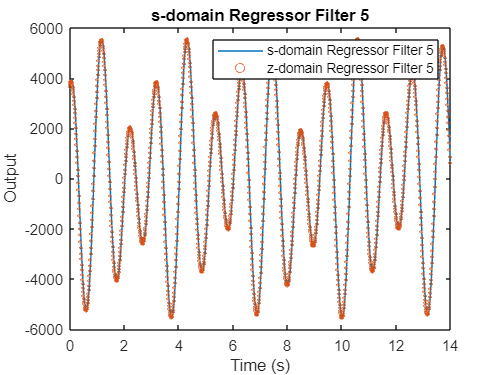

scatter(t, y, 3);
legend('s-domain Regressor Filter 5', 'z-domain Regressor Filter 5')

#### Q filters.

### 1. first filter.


$$F_1 = \frac{0.1}{s + 0.1}$$



clc
clear

% Define the transfer function G
s = tf('s');
G = (100) / (s + 100)

G =
 
    100
  -------
  s + 100
 
Continuous-time transfer function.



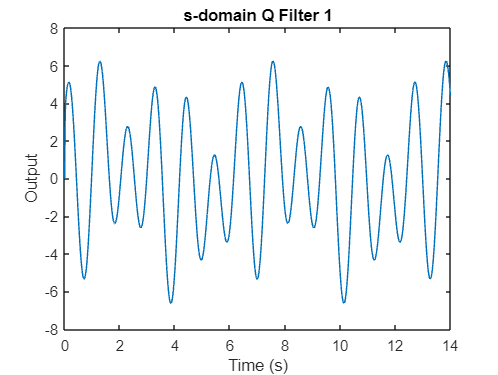


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Q Filter 1');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  0.3333 z + 0.3333
  -----------------
     z - 0.3333
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  0.3333 + 0.3333 z^-1
  --------------------
    1 - 0.3333 z^-1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =     0.3333    0.3333


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    0.3333


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 0.3333333333333333
Num(2) = 0.3333333333333333



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 0.3333333333333333


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 
        yterms = Den(2)* yk_1;
        y(i) = uterms + yterms;      
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1);
        yterms = Den(2)* y(i-1);
        y(i) = uterms + yterms; 
    end
end

uterms = 1.2454


y

y =     1.2454    2.9668    3.6586    4.0000    4.2170    4.3844    4.5269    4.6523    4.7629    4.8592    4.9410    5.0082    5.0603    5.0972    5.1186    5.1243    5.1143    5.0885    5.0469    4.9894    4.9163    4.8276    4.7235    4.6044    4.4705    4.3222    4.1599    3.9841    3.7952    3.5939    3.3806    3.1561    2.9211    2.6762    2.4223    2.1600    1.8903    1.6139    1.3318    1.0449    0.7540    0.4601    0.1641   -0.1329   -0.4301   -0.7265   -1.0211   -1.3130   -1.6011   -1.8846


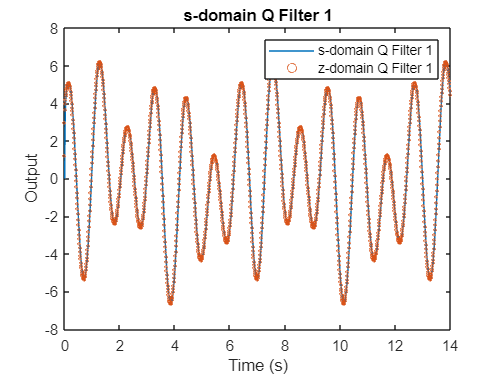

scatter(t, y, 3);
legend('s-domain Q Filter 1', 'z-domain Q Filter 1')

### 2. Second filter.


$$F_2 = \frac{10}{s + 10}$$



clc
clear

% Define the transfer function G
s = tf('s');
G = (10) / (s + 10)

G =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



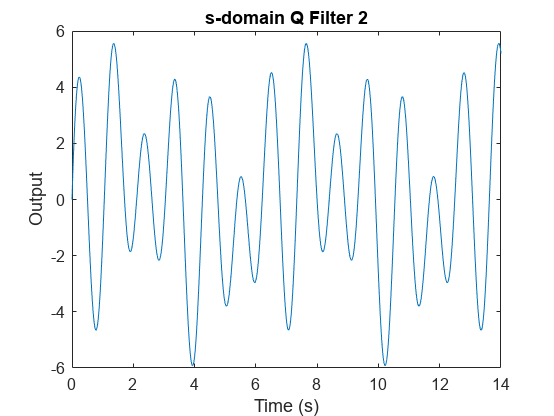


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Q Filter 2');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  0.04762 + 0.04762 z^-1
  ----------------------
     1 - 0.9048 z^-1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =     0.0476    0.0476


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    0.9048


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 0.04761904761904762
Num(2) = 0.04761904761904762



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 0.9047619047619048


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 
        yterms = Den(2)* yk_1;
        y(i) = uterms + yterms;      
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1);
        yterms = Den(2)* y(i-1);
        y(i) = uterms + yterms; 
    end
end

uterms = 0.1779


y

y =     0.1779    0.5255    0.8568    1.1724    1.4727    1.7580    2.0285    2.2844    2.5257    2.7525    2.9648    3.1626    3.3458    3.5144    3.6682    3.8071    3.9312    4.0402    4.1341    4.2128    4.2763    4.3246    4.3576    4.3755    4.3781    4.3657    4.3384    4.2963    4.2396    4.1685    4.0833    3.9843    3.8719    3.7463    3.6081    3.4577    3.2956    3.1223    2.9383    2.7443    2.5409    2.3288    2.1085    1.8809    1.6467    1.4065    1.1613    0.9118    0.6587    0.4030


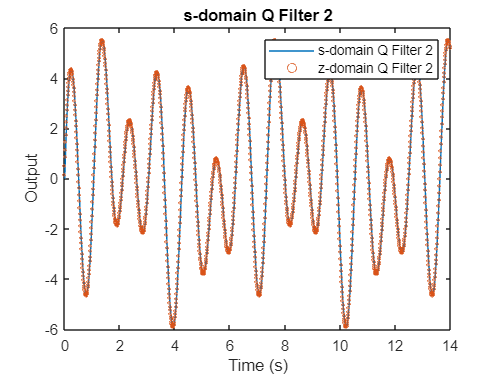

scatter(t, y, 3);
legend('s-domain Q Filter 2', 'z-domain Q Filter 2')

### 3. Third filter.


$$F_3 = \frac{1}{s + 1}$$



clc
clear

% Define the transfer function G
s = tf('s');
G = (1) / (s + 1)

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



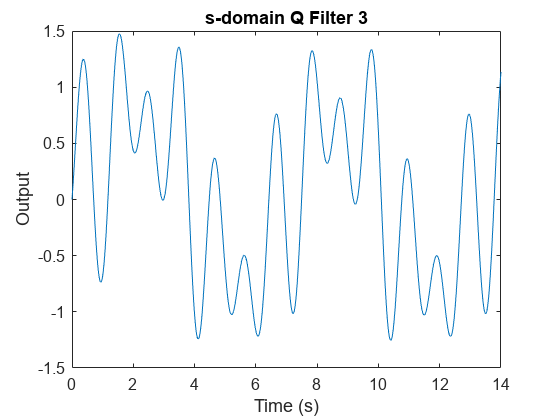


% Define the time vector t
dt = 0.01;
t = 0:dt:14;


% Generate the input signal using the voltage_input function
u = voltage_input(t);

% Use lsim to simulate the response of G to the input signal
[y_out, t_out] = lsim(G, u, t);
%[x, t] = step(G); 
% Plot the output of the transfer function G
figure;
%plot(t, x, 'LineWidth', 2);
plot(t_out, y_out);
title('s-domain Q Filter 3');
xlabel('Time (s)');
ylabel('Output');
hold all

Gz = c2d(G, 0.01, 'tustin')

Gz =
 
  0.004975 z + 0.004975
  ---------------------
        z - 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Gz.variable = 'z^-1'

Gz =
 
  0.004975 + 0.004975 z^-1
  ------------------------
       1 - 0.99 z^-1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



Num = Gz.Numerator{1}

Num =     0.0050    0.0050


2.4874e-05

ans = 2.4874e-05

Den = -Gz.Denominator{1}

Den =    -1.0000    0.9900


for i = 1:length(Num)
    fprintf('Num(%d) = %.16g\n', i, Num(i));
end

Num(1) = 0.004975124378109453
Num(2) = 0.004975124378109453



for i = 1:length(Den)
    fprintf('Den(%d) = %.16g\n', i, Den(i));
end

Den(1) = -1
Den(2) = 0.9900497512437811


y = zeros(size(t));
dt = 0.01;
t = 0:dt:14;

% Build step input
%u = ones(size(t)); 
%u(1) = 0;
%u(1) = 0;
% Initialize variables
yk_1 = 0; % Output 1 time step in the past
yk_2 = 0; % Output 2 time steps in the past
yk_3 = 0; % Output 2 time steps in the past
uk_1 = 0; % Input 1 time step in the past
uk_2 = 0; % Input 2 time steps in the past
uk_3 = 0;
% Step through time and solve the difference equation
for i = 1:length(t)
    if i == 1
        uterms = Num(1)*u(i) + Num(2)*uk_1 
        yterms = Den(2)* yk_1;
        y(i) = uterms + yterms;      
    else
        uterms = Num(1)*u(i) + Num(2)*u(i-1);
        yterms = Den(2)* y(i-1);
        y(i) = uterms + yterms; 
    end
end

uterms = 0.0186


y

y =     0.0186    0.0565    0.0958    0.1363    0.1780    0.2207    0.2642    0.3085    0.3534    0.3987    0.4443    0.4901    0.5358    0.5814    0.6266    0.6714    0.7156    0.7589    0.8014    0.8428    0.8830    0.9218    0.9591    0.9948    1.0287    1.0607    1.0907    1.1187    1.1444    1.1677    1.1887    1.2071    1.2230    1.2363    1.2468    1.2546    1.2596    1.2617    1.2610    1.2574    1.2510    1.2417    1.2295    1.2144    1.1966    1.1760    1.1526    1.1267    1.0981    1.0670


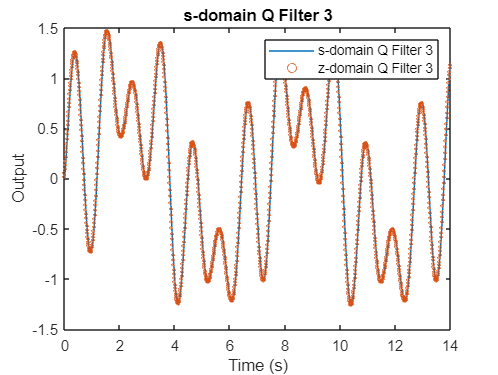

scatter(t, y, 3);
legend('s-domain Q Filter 3', 'z-domain Q Filter 3')

% Define the voltage input function

function v = voltage_input(t)
    v = sin(t) + 2*sin(4*(t + 0.5)) + 4*sin(6*t + 0.5) ;
end